# Seizure detection using raw EEG data

## Data composition:  

• 23 EEG channels (sensors) per subject based on the 10-20 EEG sensor placement guide 

• Sampling rate: All signals were sampled at **256 samples** per second  

• Resolution: 16-bit per sample 

• Naming convention: EEG_subjectXXX.mat

• 1 normal subject who did not suffer from a seizure at any time (EEG_subject000.mat) 

• 19 subjects who have at least one seizure event (EEG_subject001.mat to EEG_subject020.mat)

***Test/scrap code***

Y = magic(4)

Y =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


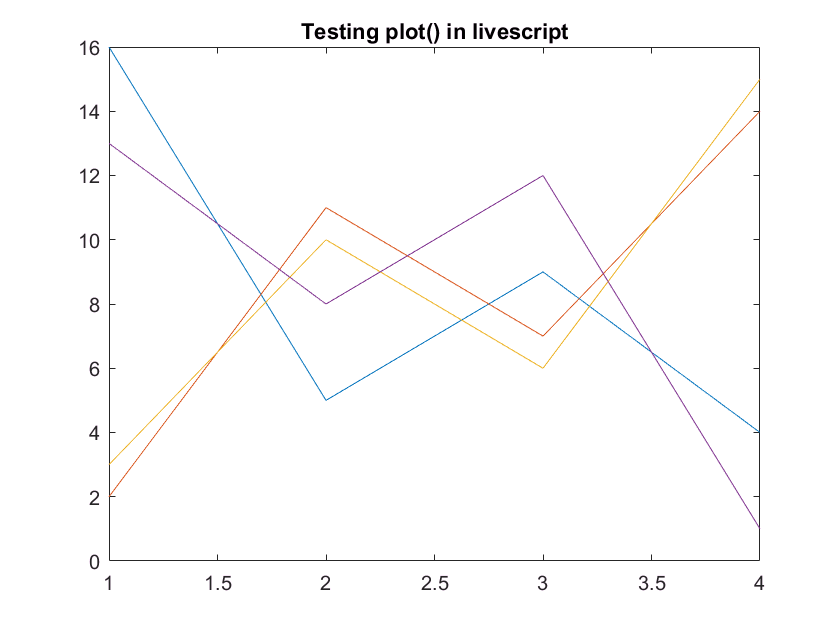

figure;
plot(Y);
title('Testing plot() in livescript');

## Preprocessing

**Input**

%% Notes
% Alpha 8 - 12
% Beta 12 - 30
% Gamma 30 - 100+
% Delta 0 - 4
% Theta 4 - 7

%%

clear
close all

% %%
% for i = 0:9
%     while i <= 9
%         i = num2str(i)
%         j = 0;
%         j = num2str(j);
%         temp = strcat('EEG_subject0',j,i);
%         EEG = load(temp);
%
%     end
% end
%         if i = 9
%             for a = 0:9
%                 load('EEG_subject0',j,i);
%             end
%         end
%     end
% end

%%
%find the waves associated with the EEG - the bands
%do filtering such as butterworth accordingly.
% do the processing indvidually
%
%% Loading the ECG file  %%
%EEGSignal.EEG(i).ch
EEGSignal = load('EEG_subject001.mat');

Error using load
Unable to read file 'EEG_subject001.mat'. No such file or directory.

fs = 256;
T = 1/fs;
nEEG = length (EEGSignal);
tECG = (1:length(EEGSignal.EEG(1).ch))*T;
%%
% Plotting Original EEG Signals
for i = 1:5
    subplot(5,1,i);
    plot(tECG, EEGSignal.EEG(i).ch);
    i= num2str(i);
    name = strcat('Original Signal','  ', i);
    title([name]);
    xlabel('time (s)');
    ylabel('Amplitude');
end
j = 1;
for i = 6:10
    if j <= 5
        subplot(5,1,j);
        plot(tECG, EEGSignal.EEG(i).ch);
        i= num2str(i);
        name = strcat('Original Signal','  ', i);
        title([name]);
        xlabel('time (s)');
        ylabel('Amplitude');
        j = j +1;
    end
end
figure;
j = 1;
for i = 11:20
    if j <= 5
        subplot(5,1,j);
        plot(tECG, EEGSignal.EEG(i).ch);
        i= num2str(i);
        name = strcat('Original Signal','  ', i);
        title([name]);
        xlabel('time (s)');
        ylabel('Amplitude');
        j = j +1;
    end
end
figure;
j = 1;
for i = 21:23
    if j <= 3
        subplot(3,1,j);
        plot(tECG, EEGSignal.EEG(i).ch);
        i= num2str(i);
        name = strcat('Original Signal','  ', i);
        title([name]);
        xlabel('time (s)');
        ylabel('Amplitude');
        j = j +1;
    end
end

Plot raw data:

%plot();

**Filtering**

## Feature Extraction

Plot Features:

%plot();

## Pattern classification

SVM, KNN, or LDF?

- Need to compare

- Depends on selected features

% Attach KNN or LDF code 
% Input: Features (x1, x2, x3, ..., class label) in time-series
% Output: Classifier (1[true] or 0[false], time-instance)

## Parameter tuning

K-fold Cross Validation

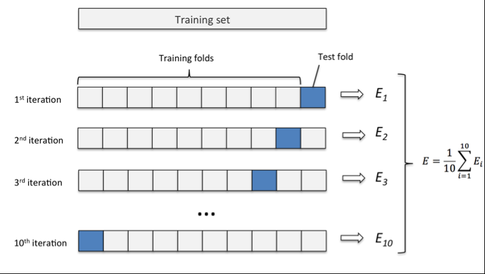

        https://sebastianraschka.com/faq/docs/evaluate-a-model.html

% for 'n' samples